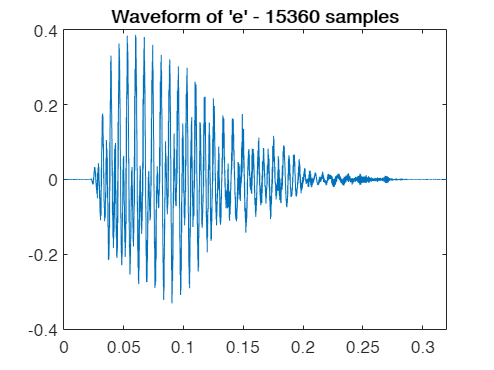

[y, fs] = audioread('e-vowel-utterance.wav');
y1 = y(:,1);
y1 = y1(27000:end);
y1 = y1(1:15360);
n = 1/fs:1/fs:length(y1)/fs;
l = length(y1);
figure;
plot(n, y1);
title("Waveform of 'e' - 15360 samples");

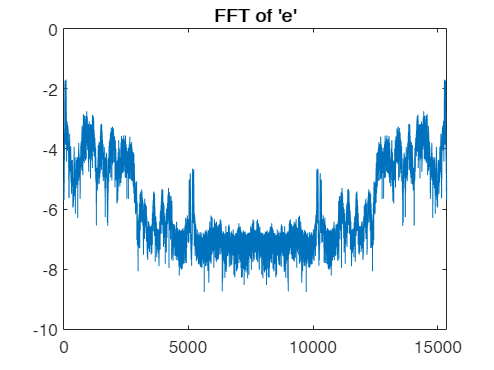

% Complete spectrum
fy1 = fft(y1);
figure;
plot(log10(abs(fy1)/l));
title("FFT of 'e'");

ham = hamming(512, "symmetric");
lh = length(ham);
% Assumed 50% overlap, with 512-bit window
y_split = zeros(length(1:lh/2:l-lh/2), lh);
yw = zeros(length(1:lh/2:l-lh/2), lh);
size(yw);

index = 1;
for i=1:lh/2:l-lh/2
    y_split(index, :) = (y1(i:i+lh-1));
    yw(index, :) = (y1(i:i+lh-1).*ham);
    index=index+1;
end

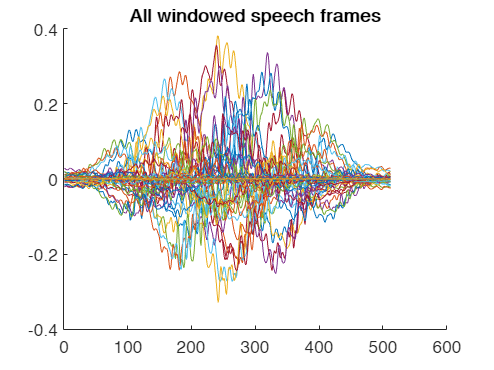

figure;
hold on;
for i=1:59
    plot(1:512, yw(i,:))
end
title("All windowed speech frames");
hold off;

eta = 256;
R = zeros(eta, 59);

% Extending window to 1536 length
ham_ = zeros(lh*3, 1);
ham_(lh:2*lh-1) = ham;

for i=1:59
    R_ = 0;
    y_ = ham_;
    if (i-1 < 1)
        y_(1:lh) = zeros(lh, 1);
    else
        y_(1:lh) = y_split(i-1, :);
    end

    y_(lh+1:2*lh) = y_split(i, :);

    if (i+1 > 59)
        y_(2*lh+1:3*lh) = zeros(lh, 1);
    else
        y_(2*lh+1:3*lh) = y_split(i+1, :);
    end
    for eta=1:256
        for j=1:lh
            R_ = R_ + ham_(2*lh-j)*y_(j)*ham_(2*lh-j-eta)*y_(j+eta);
        end
        R(eta, i) = R_;
    end
end

nthframe = 20

nthframe = 20

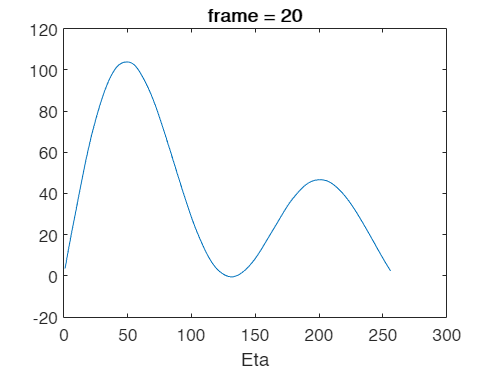

figure;
plot(R(:,nthframe));
title("frame = "+ nthframe);
xlabel("Eta");

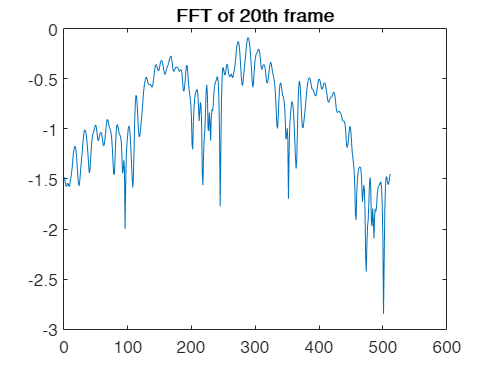

% Now computing the fft of each frame
fR = fft(yw);
figure;
plot(log10(abs(fR(nthframe, :))))
title("FFT of "+nthframe+"th frame")

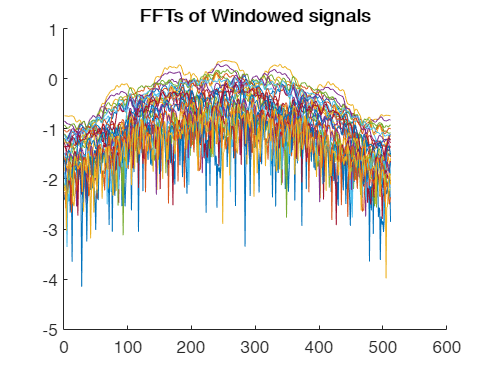

figure;
hold on;
for i=1:59
    plot(log10(abs(fR(i, :))));
end
title("FFTs of Windowed signals")
hold off;

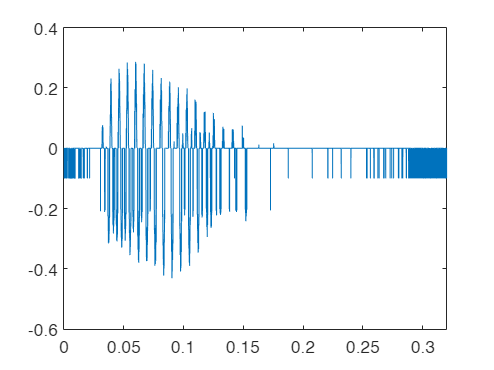

% Now start by clipping off y1
clip_amp = 0.1;
for i=1:length(y1)
    if(y1(i)<clip_amp && y1(i)>0)
        y1(i)=0;
    elseif(y1(i)>-clip_amp && y1(i)<0)
        y1(i)=0;
    else
        y1(i)=y1(i)-clip_amp;
    end
end
plot(n, y1);

% Now re-run from line 10